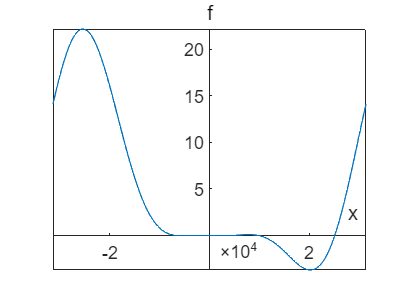

ezplot(@f,[-pi,pi])
ax=gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
axis([-inf inf -inf inf]);

L1=3;
L2=3*sqrt(2);
L3=3;
gamma=pi/4;
p1=5;
p2=7;
p3=3;
x1=5;
x2=0;
y2=6;
t1=fzero(@f,2)

t1 =    2.513852799350384


t2=fzero(@f,1)

t2 =    0.977672895000363


t3=fzero(@f,0.5)

t3 =    0.458878181048990


t4=fzero(@f,0)

t4 =    0.037766760575913


t5=fzero(@f,-0.3)

t5 =   -0.354740270415674


t6=fzero(@f,-1)

t6 =   -0.673157486371673


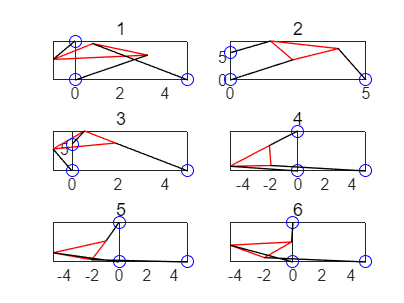

theta=[t1,t2,t3,t4,t5,t6];
A2=L3.*cos(theta)-x1;
B2=L3.*sin(theta);
A3=L2.*(cos(theta).*cos(gamma)-sin(theta).*sin(gamma))-x2;
B3=L2.*(cos(theta).*sin(gamma)+sin(theta).*cos(gamma))-y2;
D=2.*(A2.*B3-B2.*A3);
M1=p2.^2-p1.^2-A2.^2-B2.^2;
M2=p3.^2-p1.^2-A3.^2-B3.^2;
N1=B3.*M1-B2.*M2;
N2=-A3.*M1+A2.*M2;
u1=N1./D;
v1=N2./D;
u2=u1+L3.*cos(theta);
v2=v1+L3.*sin(theta);
u3=L2.*cos(theta+gamma)+u1;
v3=L2.*sin(theta+gamma)+v1;
figure
for i=1:6
    subplot(3,2,i);
    plot([u1(i) u2(i) u3(i) u1(i)],[v1(i) v2(i) v3(i) v1(i)],'r');hold on
    plot([0 x1 x2],[0 0 y2],'bo');hold on
    plot([0 u1(i) 0],[0 v1(i) 0],'k');hold on
    plot([x1 u2(i) x1],[0 v2(i) 0],'k');hold on
    plot([x2 u3(i) x2],[y2 v3(i) y2],'k')
    ax=gca;
    ax.XAxisLocation = 'origin';
    ax.YAxisLocation = 'origin';
    axis([-inf inf -inf inf]);
    title(i)
end

function out=f(theta)
format long;
L1=3;
L2=3*sqrt(2);
L3=3;
gamma=pi/4;
p1=5;
p2=7;
p3=3;
x1=5;
x2=0;
y2=6;
A2=L3.*cos(theta)-x1;
B2=L3.*sin(theta);
A3=L2.*(cos(theta).*cos(gamma)-sin(theta).*sin(gamma))-x2;
B3=L2.*(cos(theta).*sin(gamma)+sin(theta).*cos(gamma))-y2;
D=2.*(A2.*B3-B2.*A3);
M1=p2.^2-p1.^2-A2.^2-B2.^2;
M2=p3.^2-p1.^2-A3.^2-B3.^2;
N1=B3.*M1-B2.*M2;
N2=-A3.*M1+A2.*M2;
out=N1.^2+N2.^2-p1.^2*D.^2;
end